p = load('C:\dev\biomedeng\Associated Files\Chapter 15\proj_prof1.mat')

p = struct with fields:
    p: [185×180 double]


p = p.p

p =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0   


[I_b,f] = iradon(p, 1, "none")% Inverse Radon Transform

I_b =     9.3812    9.4468    9.5212    9.5966    9.6734    9.7519    9.8283    9.9068    9.9933   10.0689   10.1433   10.2287   10.3026   10.3873   10.4664   10.5507   10.6343   10.7150   10.7960   10.8767   10.9576   11.0378   11.1214   11.2054   11.2866   11.3691   11.4458   11.5236   11.6080   11.6849   11.7656   11.8441   11.9174   11.9882   12.0699   12.1409   12.2119   12.2868   12.3658   12.4304   12.4874   12.5408   12.5974   12.6664   12.7433   12.8099   12.8554   12.9009   12.9462   12.9937
    9.4468    9.5368    9.5997    9.6764    9.7583    9.8328    9.9160    9.9978   10.0744   10.1650   10.2462   10.3209   10.4070   10.4876   10.5743   10.6553   10.7397   10.8294   10.9151   10.9941   11.0774   11.1620   11.2491   11.3339   11.4165   11.5012   11.5851   11.6697   11.7500   11.8319   11.9174   11.9914   12.0685   12.1538   12.2323   12.3040   12.3807   12.4630   12.5385   12.5999   12.6633   12.7247   12.7831   12.8561   12.9324   12.9983   13.0498   13.1015   13.1507   

f =      1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1     1


I_b = mat2gray(I_b)

I_b =     0.0023    0.0034    0.0045    0.0057    0.0069    0.0082    0.0094    0.0106    0.0120    0.0132    0.0144    0.0158    0.0169    0.0183    0.0195    0.0209    0.0222    0.0235    0.0248    0.0260    0.0273    0.0286    0.0299    0.0312    0.0325    0.0338    0.0351    0.0363    0.0376    0.0388    0.0401    0.0414    0.0425    0.0437    0.0450    0.0461    0.0472    0.0484    0.0496    0.0507    0.0516    0.0524    0.0533    0.0544    0.0556    0.0567    0.0574    0.0581    0.0589    0.0596
    0.0034    0.0048    0.0058    0.0070    0.0083    0.0095    0.0108    0.0121    0.0133    0.0147    0.0160    0.0172    0.0186    0.0199    0.0212    0.0225    0.0239    0.0253    0.0266    0.0279    0.0292    0.0306    0.0319    0.0333    0.0346    0.0359    0.0373    0.0386    0.0399    0.0412    0.0425    0.0437    0.0449    0.0463    0.0475    0.0487    0.0499    0.0512    0.0524    0.0534    0.0544    0.0553    0.0563    0.0574    0.0586    0.0597    0.0605    0.0613    0.0621   


b = fspecial('unsharp')%Unsharp filter

b =    -0.1667   -0.6667   -0.1667
   -0.6667    4.3333   -0.6667
   -0.1667   -0.6667   -0.1667


I_f1 = imfilter(I_b, b)

I_f1 =     0.0048    0.0053    0.0078    0.0102    0.0126    0.0151    0.0174    0.0198    0.0228    0.0250    0.0271    0.0301    0.0321    0.0350    0.0373    0.0401    0.0427    0.0451    0.0476    0.0502    0.0527    0.0552    0.0578    0.0605    0.0630    0.0657    0.0679    0.0702    0.0731    0.0753    0.0779    0.0805    0.0827    0.0846    0.0875    0.0896    0.0917    0.0940    0.0967    0.0987    0.1004    0.1019    0.1035    0.1057    0.1084    0.1107    0.1117    0.1131    0.1145    0.1161
    0.0053    0.0054    0.0055    0.0068    0.0084    0.0093    0.0108    0.0122    0.0130    0.0149    0.0162    0.0169    0.0187    0.0197    0.0213    0.0224    0.0237    0.0254    0.0268    0.0278    0.0291    0.0305    0.0320    0.0333    0.0345    0.0359    0.0372    0.0387    0.0398    0.0411    0.0427    0.0436    0.0447    0.0464    0.0476    0.0485    0.0497    0.0513    0.0526    0.0532    0.0543    0.0553    0.0560    0.0573    0.0587    0.0598    0.0604    0.0613    0.0621  

I_f2 = imfilter(I_f1, b)%Apply twice

I_f2 =     0.0127    0.0090    0.0177    0.0236    0.0292    0.0361    0.0414    0.0468    0.0559    0.0600    0.0645    0.0740    0.0771    0.0855    0.0903    0.0978    0.1046    0.1100    0.1162    0.1227    0.1292    0.1348    0.1414    0.1483    0.1543    0.1614    0.1664    0.1716    0.1799    0.1846    0.1911    0.1980    0.2035    0.2068    0.2154    0.2201    0.2252    0.2303    0.2383    0.2431    0.2471    0.2504    0.2541    0.2596    0.2669    0.2731    0.2746    0.2780    0.2811    0.2856
    0.0090    0.0046    0.0003    0.0018    0.0038    0.0015    0.0030    0.0037    0.0007    0.0042    0.0041    0.0013    0.0040    0.0024    0.0041    0.0029    0.0025    0.0041    0.0046    0.0029    0.0036    0.0036    0.0042    0.0043    0.0037    0.0042    0.0042    0.0049    0.0042    0.0041    0.0060    0.0041    0.0037    0.0058    0.0055    0.0043    0.0046    0.0060    0.0065    0.0044    0.0053    0.0061    0.0047    0.0058    0.0063    0.0061    0.0055    0.0066    0.0068  

I_f1 =     0.0065    0.0070    0.0095    0.0118    0.0142    0.0167    0.0190    0.0214    0.0244    0.0265    0.0286    0.0317    0.0336    0.0365    0.0388    0.0416    0.0442    0.0466    0.0491    0.0516    0.0542    0.0566    0.0592    0.0619    0.0643    0.0670    0.0692    0.0715    0.0744    0.0766    0.0792    0.0817    0.0839    0.0858    0.0887    0.0908    0.0929    0.0952    0.0979    0.0999    0.1016    0.1030    0.1047    0.1068    0.1095    0.1117    0.1128    0.1142    0.1155    0.1171
    0.0070    0.0071    0.0072    0.0085    0.0101    0.0110    0.0125    0.0139    0.0146    0.0166    0.0178    0.0186    0.0203    0.0213    0.0229    0.0240    0.0253    0.0270    0.0284    0.0293    0.0307    0.0320    0.0335    0.0348    0.0360    0.0374    0.0387    0.0402    0.0413    0.0426    0.0442    0.0450    0.0462    0.0478    0.0490    0.0499    0.0511    0.0527    0.0540    0.0546    0.0557    0.0567    0.0574    0.0587    0.0601    0.0611    0.0618    0.0627    0.0635  

I_f2 =     0.0211    0.0176    0.0260    0.0318    0.0373    0.0440    0.0491    0.0544    0.0633    0.0673    0.0717    0.0810    0.0840    0.0922    0.0969    0.1042    0.1108    0.1161    0.1221    0.1285    0.1348    0.1403    0.1468    0.1534    0.1593    0.1662    0.1711    0.1762    0.1842    0.1888    0.1952    0.2019    0.2073    0.2106    0.2189    0.2235    0.2285    0.2335    0.2413    0.2460    0.2498    0.2530    0.2567    0.2620    0.2691    0.2752    0.2767    0.2800    0.2830    0.2874
    0.0176    0.0132    0.0090    0.0106    0.0125    0.0102    0.0117    0.0124    0.0094    0.0129    0.0128    0.0101    0.0127    0.0111    0.0128    0.0116    0.0112    0.0128    0.0133    0.0116    0.0123    0.0123    0.0129    0.0130    0.0124    0.0128    0.0129    0.0136    0.0128    0.0128    0.0146    0.0127    0.0124    0.0144    0.0142    0.0129    0.0132    0.0146    0.0151    0.0131    0.0140    0.0147    0.0134    0.0144    0.0149    0.0147    0.0142    0.0152    0.0154  

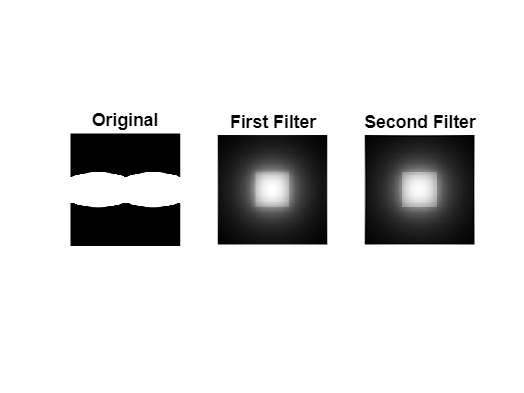

subplot(1, 3, 1)
imshow(p)
title('Original')

subplot(1, 3, 2)
imshow(I_f1)
title("First Filter")

subplot(1, 3, 3)
imshow(I_f2)
title("Second Filter")